输入文件是modified_file，是已经删除负数的文件,在正式使用时还需进行其他的处理。

# 输入文件

filename = 'modified_file.xlsx'; % Excel 文件名
data = readtable(filename); % 读取整个表格数据

# 数据处理

% 获取数据的行数和列数
[numRows, numCols] = size(data);

% 计算数据分组数，每三列为一组数据（假设数据格式是 [电压, 循环序号, dQ/dV]）
numGroups = numCols / 3;

% 初始化数据存储变量
voltage_col = [];
dqdv_col = [];
cycle_col = [];

% 遍历每组数据
for i = 1:numGroups
    % 提取每组三列数据
    voltage_col(numRows*(i-1)+1:numRows*i,1) = table2array(data(:, (i-1)*3 + 1)); % 电压 (V)-第一列
    dqdv_col(numRows*(i-1)+1:numRows*i,1) = table2array(data(:, (i-1)*3 + 3)); % dQ/dV (mAh/V)-第2列
    cycle_col(numRows*(i-1)+1:numRows*i,1) = table2array(data(:, (i-1)*3 + 2)); % 循环序号-第3列
end

**之后如果要修改感觉可以在这里，添加查找负数索引**

% 查找 voltage_col 中的 NaN 值索引，并同步删除相关数据
A = find(isnan(voltage_col));
voltage_col(A) = [];
dqdv_col(A) = [];
cycle_col(A) = [];

% 生成等高线网格
[xf, yf] = meshgrid(min(voltage_col):0.001:max(voltage_col), 0:0.1:100);
zf = griddata(voltage_col, cycle_col, dqdv_col, xf, yf); % 插值计算 dQ/dV

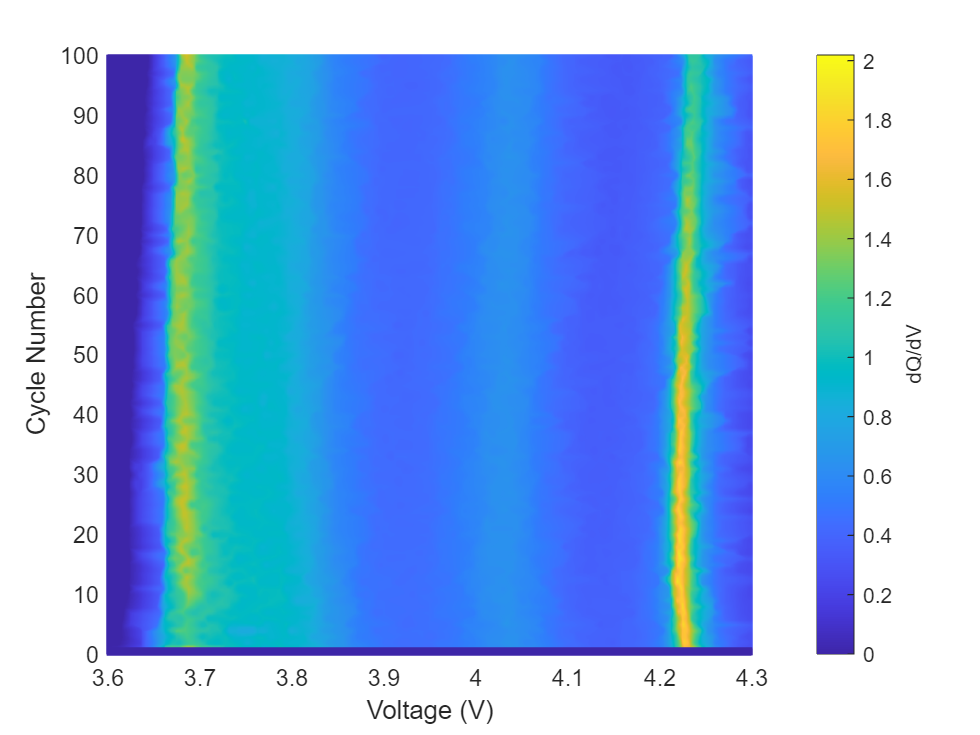


% 将 NaN 值设为 0，避免绘图出现空白区域
zf(isnan(zf)) = 0;

% 重新调整数据形状，以用于 3D 绘图
voltage_col = reshape(xf, [1, size(xf,1) * size(xf,2)]);
cycle_col = reshape(yf, [1, size(yf,1) * size(yf,2)]);
dqdv_col = reshape(zf, [1, size(zf,1) * size(zf,2)]);

% 绘制 3D 散点图
KK = 1; % 采样间隔
figure;
scatter3(downsample(voltage_col, KK), downsample(dqdv_col, KK), downsample(cycle_col, KK), ...
    2.5, downsample(dqdv_col, KK), 'filled'); % 颜色表示 dQ/dV
cb = colorbar; % 添加颜色条
cb.Label.String = 'dQ/dV'; % 颜色条标签

% 视角设置
view(0, 0); 
view([0 0]); % 俯视视角

% 添加坐标轴标签
xlabel('Voltage (V)');
zlabel('Cycle Number');
hold off;

% 调整 X 轴的范围
xlim([3.6 4.3]); % 限定电压范围

# 输出

% 强制转换为列向量
voltage_col = voltage_col(:); 
cycle_col = cycle_col(:);
dqdv_col = dqdv_col(:);

data=[voltage_col,dqdv_col,cycle_col];
writematrix(data,"chazhi-data.txt",'Delimiter', 'tab');